# Cálculos Para Mecanismos de 4 y 5 Barras

Eduardo Santizo Olivet (16089)

### Mecanismo de 4 Barras

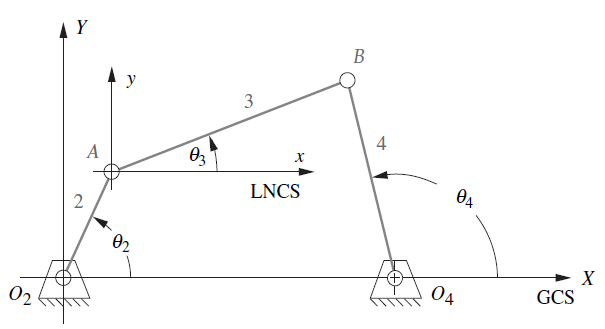

clear;

% DIMENSIONAMIENTO INICIAL -------------------------------------------------

% Posición Inicial
Theta2_o = 0;                                                                   % Posición angular inicial (Grados)
Theta2 = linspace(Theta2_o, 360 + Theta2_o, 361);                               % Vector con todos los ángulos desde Theta2_o hasta completar una revolución

% Velocidad Angular Inicial
Omega2 = zeros(size(Theta2));                                                   % Vector de ceros con las mismas dimensiones que Theta 2
Omega2(1) = 15;                                                                 % Velocidad angular inicial (rad/s)

% Aceleración Angular Inicial
Alpha2 = 0;                                                                     % Aceleración angular constante (rad/s^2)

% Conversión de Aceleración y Velocidad angular a °/s
Alpha2 = Alpha2 * (180/pi);
Omega2(1) = Omega2(1) * (180/pi);

% Cálculo de los deltas de tiempo 
% DESCRIPCIÓN: Deltas de tiempo que requiere el mecanismo para pasar de
% posición angular a posición angular. También se calcula el valor de la
% velocidad angular del eslabón de entrada
DeltaTiempo = zeros(size(Theta2));

for i = 1:size(Theta2,2)-1
    Soluciones = roots([0.5*Alpha2 Omega2(i) Theta2(i)-Theta2(i+1)]);           % Raices de ecuación cuadrática: (1/2)Ao t^2 + Vo t + (Xo - Xf) = 0
    
    if isempty(Soluciones) || (Soluciones < 0)
        disp("Error: Delta de Tiempo Inválido. Tiempos negativos o nulos obtenidos");
        break;
    else
        DeltaTiempo(i) = Soluciones(Soluciones >= 0);                           % Se guarda el tiempo positivo obtenido al resolver la ecuación cuadrática
    end
   
    Omega2(i+1) = Omega2(i) + Alpha2*DeltaTiempo(i);                            % Cálculo de la velocidad angular luego de cada delta de tiempo.
end

% Transformación con respecto a las "Coordenadas Globales"
% DESCRIPCIÓN: Esta variable determina la cantidad de grados que se inclina el mecanismo
% con respecto a su disposición u orientación "estándar"
% OPCIONES:
% Ángulos positivos = Ángulo por encima del eje X
% Ángulos negativos = Ángulo por debajo del eje X
GlobalOffset = 0;

% Largo de cada eslabón
d = 174;                                                         % Bancada
a = 114;                                                         % Entrada
b = 108;                                                         % Acoplador 
c = 110;                                                         % Salida

% Largo de dimensiones de acoplador triangular 
l = 1;      % Parte de la base
r = 1;      % Alto

% Puntos Adicionales a Graficar
x = [-0.6 0.6 2.3 3 0.9 1.3 0.2 -0.1 -0.6];
y = [3 4 5 6 5.3 4.5 4.8 4.4 3.5];

% TIPO DE MECANISMO --------------------------------------------------------

% Condición de Grashof
Short = min([a b c d]);
Long = max([a b c d]);
PQ = sum([a b c d])-(Short+Long);

if (Short + Long) < PQ
    disp('Mecanismo Grashof');
    Grashof = "Grashof";
elseif (Short + Long) == PQ
    disp('Mecanismo Especial Grashof');
    Grashof = "Especial";
else
    disp('Mecanismo No Grashof');
    Grashof = "No Grashof";
end

Mecanismo No Grashof


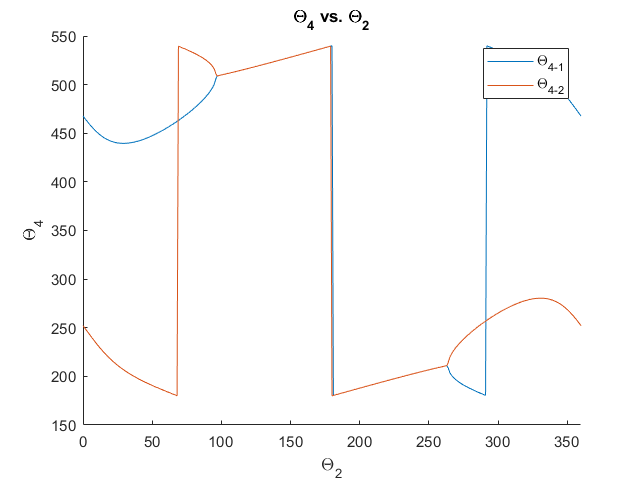


% SINTESIS DE POSICIÓN -----------------------------------------------------

% Síntesis de posición calculada en función de las ecuaciones
% proporcionadas por Robert L. Norton en su libro: "Diseño de Maquinaria".
% Para más información ver pags. 161 - 167

% Constantes K
K1 = d/a;
K2 = d/c;
K3 = (a^2 - b^2 + c^2 + d^2)/(2*a*c);
K4 = d/b;
K5 = (c^2 - d^2 - a^2 - b^2)/(2*a*b);

% Constantes A-F
A = cosd(Theta2) - K1 - (K2 .* cosd(Theta2)) + K3;
B = -2 * sind(Theta2);
C = K1 - ((K2+1) .* cosd(Theta2)) + K3;
D = cosd(Theta2) - K1 + (K4 .* cosd(Theta2)) + K5;
E = -2 .* sind(Theta2);
F = K1 + ((K4-1) .* cosd(Theta2)) + K5;

% Theta 4
Theta4(1,:) = real(2*atand((-B-sqrt(B.^2 - 4*A.*C))./(2.*A)) + GlobalOffset);
Theta4(2,:) = real(2*atand((-B+sqrt(B.^2 - 4*A.*C))./(2.*A)) + GlobalOffset);

% Theta 4 ya compensa por el Global Offset. Para que al graficar Theta 2
% también tome en cuenta el Global Offset, se le suma "GlobalOffset"
Theta2 = Theta2 + GlobalOffset;                                                    

% Si existen ángulos inferiores a 0 en Theta 4 se les suma 360° a todos
% los ángulos para eliminar los signos negativos
for i = 1:2
    if isempty(Theta4(Theta4(i,:) < 0)) == 0
        Theta4(i,:) = Theta4(i,:) + 360;
    end
end

% Gráfica de Theta 4 vs Theta 2
figure(1); clf; hold on
plot(Theta2, Theta4(1,:));
plot(Theta2, Theta4(2,:));
legend("\Theta_{4-1}", "\Theta_{4-2}")
title("\Theta_{4} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{4}");
xlim([GlobalOffset 360+GlobalOffset])

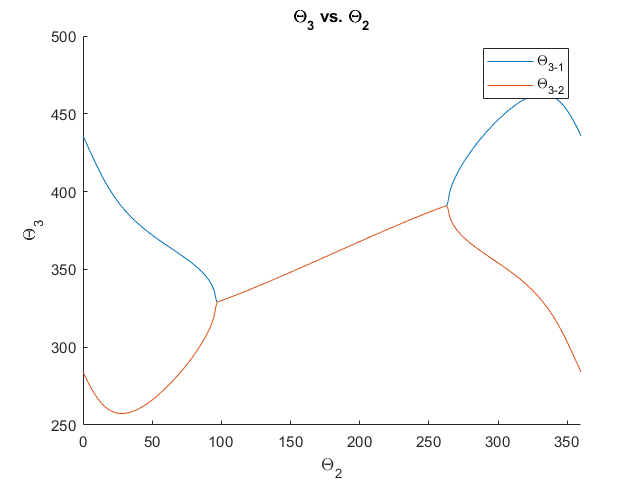

Theta2 = Theta2 - GlobalOffset;

% Theta 3
Theta3(1,:) = real(2*atand((-E-sqrt(E.^2 - 4.*D.*F))./(2.*D)) + GlobalOffset);
Theta3(2,:) = real(2*atand((-E+sqrt(E.^2 - 4.*D.*F))./(2.*D)) + GlobalOffset);

Theta2 = Theta2 + GlobalOffset;  

for i = 1:2
    if isempty(Theta3(Theta3(i,:) < 0)) == 0
        Theta3(i,:) = Theta3(i,:) + 360;
    end
end

figure(2); clf; hold on
plot(Theta2, Theta3(1,:));
plot(Theta2, Theta3(2,:));
legend("\Theta_{3-1}", "\Theta_{3-2}")
title("\Theta_{3} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{3}");
xlim([GlobalOffset 360+GlobalOffset])

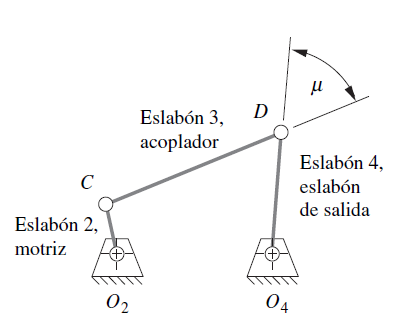

% Tabla con Theta2, Theta3 y Theta4
% NOTA: Si da un error, esto significa que la hoja de excel está abierta o siendo
% utilizada por algún otro programa.
delete 'Analisis Mecanismo.xls';

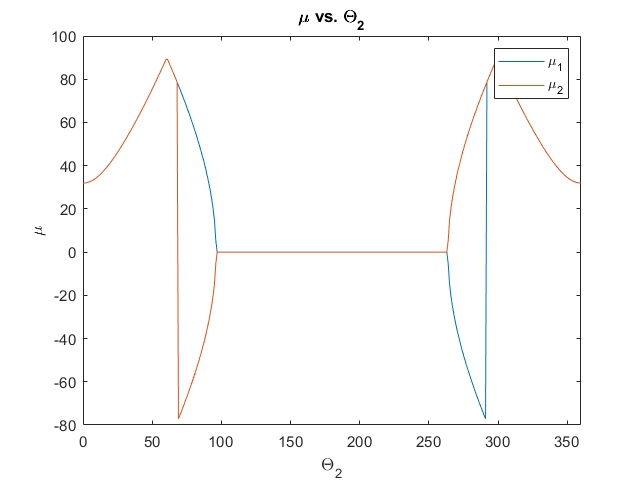

TableRange = (GlobalOffset:15:361+GlobalOffset) + 1;
TableData = [Theta2(:,TableRange)' Theta3(:,TableRange)' Theta4(:,TableRange)'];
PosTable = array2table(TableData,'VariableNames',{'Theta2','Theta3_1','Theta3_2','Theta4_1','Theta4_2'});
PosTable = rows2vars(PosTable);
writetable(PosTable, 'Analisis Mecanismo.xls', 'Sheet', 1);


% ÁNGULO DE TRANSMISIÓN ----------------------------------------------------

Mu = abs(Theta3 - Theta4);                      % Diferencia entre los ángulos Theta3 y Theta4
Mu(Mu > 90) = 180 - Mu(Mu > 90);                % Todos los valores de Mu mayores a 90 se compensan

figure(3); clf;
plot(Theta2, Mu);
title("\mu vs. \Theta_2");
legend("\mu_1", "\mu_2")
xlabel("\Theta_2");
ylabel("\mu");
xlim([GlobalOffset 360+GlobalOffset])

% ANÁLISIS DE VELOCIDAD ----------------------------------------------------

% Modo a visualizar
% Modo 1 = Normal
% Modo 2 = Inversión
Modo = 1;

% Velocidades Angulares
Omega2 = Omega2 * (pi/180);

Omega3 = (a*Omega2/b) .* (sind(Theta4(Modo,:) - Theta2) ./ sind(Theta3(Modo,:) - Theta4(Modo,:)));
Omega4 = (a*Omega2/c) .* (sind(Theta2 - Theta3(Modo,:)) ./ sind(Theta4(Modo,:) - Theta3(Modo,:)));

% Si se detectan velocidades infinitas, se establece que el mecanismo
% aunque sea Grashof, consiste de una paradoja no grashof.
if sum(isinf(Omega3) + isinf(Omega4)) > 0
    disp("Paradoja de Grashof");
    Grashof = "No Grashof";
end

Paradoja de Grashof


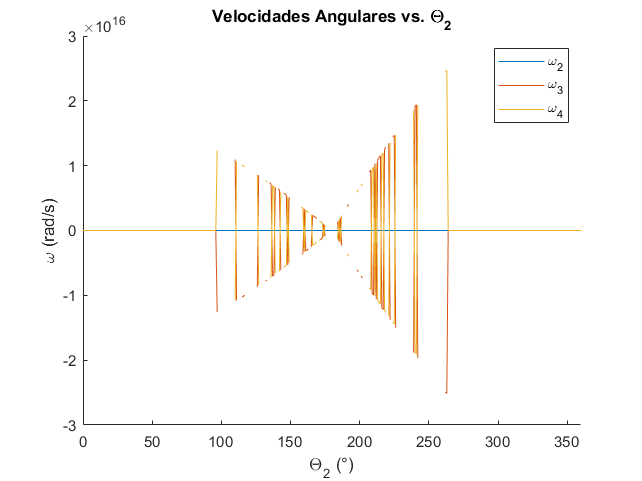


figure(4); clf; hold on
plot(Theta2, Omega2);
plot(Theta2, Omega3);
plot(Theta2, Omega4);
legend("\omega_2", "\omega_3", "\omega_4")
title("Velocidades Angulares vs. \Theta_2");
xlabel("\Theta_2 (°)");
ylabel("\omega (rad/s)");
xlim([GlobalOffset 360+GlobalOffset])

% ANÁLISIS DE ACELERACIÓN --------------------------------------------------

P = c*sind(Theta4(Modo,:));
Q = b*sind(Theta3(Modo,:));
R = a*Alpha2*sind(Theta2) + a*Omega2.^2.*cosd(Theta2) + b*Omega3.^2.*cosd(Theta3(Modo,:)) - c*Omega4.^2.*cosd(Theta4(Modo,:));
S = c*cosd(Theta4(Modo,:));
T = b*cosd(Theta3(Modo,:));
U = a*Alpha2*cosd(Theta2) - a*Omega2.^2.*sind(Theta2) - b*Omega3.^2.*sind(Theta3(Modo,:)) + c*Omega4.^2.*sind(Theta4(Modo,:));

Alpha3 = (R.*S - P.*U) ./ (P.*T - Q.*S);
Alpha4 = (R.*T - Q.*U) ./ (P.*T - Q.*S);

% Si se detectan aceleraciones infinitas, se establece que el mecanismo
% aunque sea Grashof, consiste de una paradoja no grashof.
if sum(isinf(Alpha3) + isinf(Alpha4)) > 0
    disp("Paradoja de Grashof");
    Grashof = "No Grashof";
end

Paradoja de Grashof


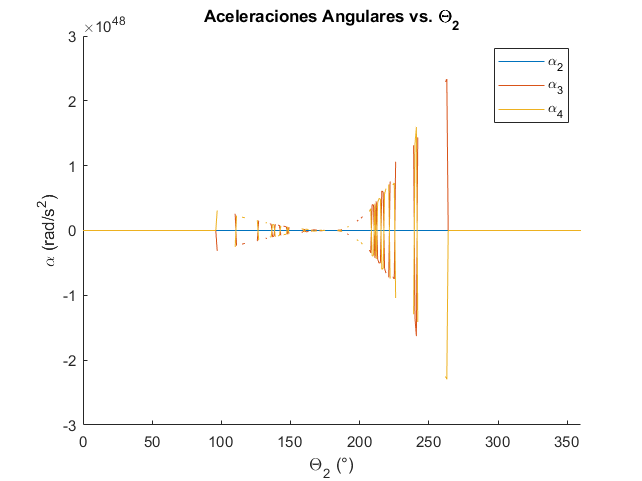


figure(5); clf; hold on
plot(Theta2, Alpha2*ones(size(Theta2)));
plot(Theta2, Alpha3);
plot(Theta2, Alpha4);
legend("\alpha_2", "\alpha_3", "\alpha_4");
title("Aceleraciones Angulares vs. \Theta_2");
xlabel("\Theta_2 (°)");
ylabel("\alpha (rad/s^2)");
xlim([GlobalOffset 360+GlobalOffset])

% Tabla con Theta2, Omegas y Alphas

TableData = [Theta2(:,TableRange)' Omega2(:,TableRange)' Omega3(:,TableRange)' Omega4(:,TableRange)' Alpha2*ones(size(TableRange))' Alpha3(:,TableRange)' Alpha4(:,TableRange)'];
VelTable = array2table(TableData,'VariableNames',{'Theta2','Omega2','Omega3','Omega4','Alpha2','Alpha3','Alpha4'});
VelTable = rows2vars(VelTable);
writetable(VelTable, 'Analisis Mecanismo.xls', 'Sheet', 2);



% ÁNGULOS DE AGARROTAMIENTO ------------------------------------------------

% Ángulo en el que Mu = 0. Debido a que la síntesis de posición se obtiene
% en unidades discretas (0, 1, 2, ... 360), puede que no se encuentre un ángulo 
% en el que Mu sea exactamente = 0. Por esto, se encuentra el valor mínimo de
% Mu. De esta manera se encuentra el Theta2 más cercano al valor mínimo.

[~, Theta2_Agarrotamiento] = min(Mu,[],2);

% Si el mecanismo es grashof (O es un caso especial) no existe
% agarrotamiento
if Grashof ~= "No Grashof"
    Theta2_Agarrotamiento = [0; 0];
    Theta2_Limites = [0 360; 0 360];
end

% Ángulos en los que el movimiento está definido
for i = 1:size(Theta2_Agarrotamiento,1)
    if Theta2_Agarrotamiento(i) > 180
        Theta2_Limites(i,:) = [360-Theta2_Agarrotamiento(i) Theta2_Agarrotamiento(i)];
    else
        Theta2_Limites(i,:) = [Theta2_Agarrotamiento(i) 360-Theta2_Agarrotamiento(i)];
    end
end

% Print de los ángulos de agarrotamiento (Utilizado solo como referencia)
%disp(strcat("Theta 2 - ° de Agarrotamiento 1: ", num2str(Theta2_Agarrotamiento(1)-1)));
%disp(strcat("Theta 2 - ° de Agarrotamiento 2: ", num2str(Theta2_Agarrotamiento(2)-1)));


#### Animación del Mecanismo

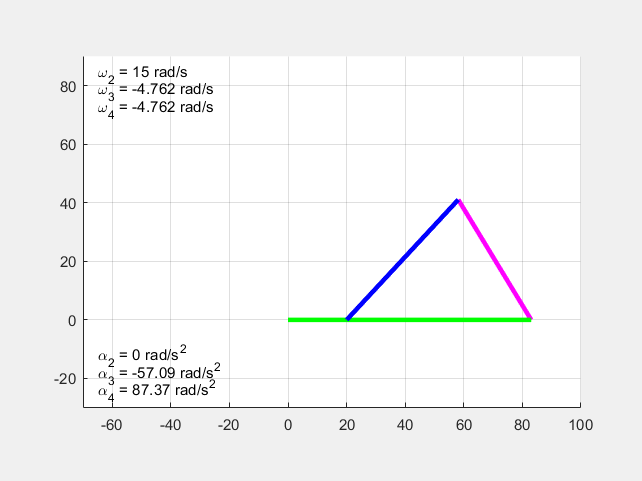

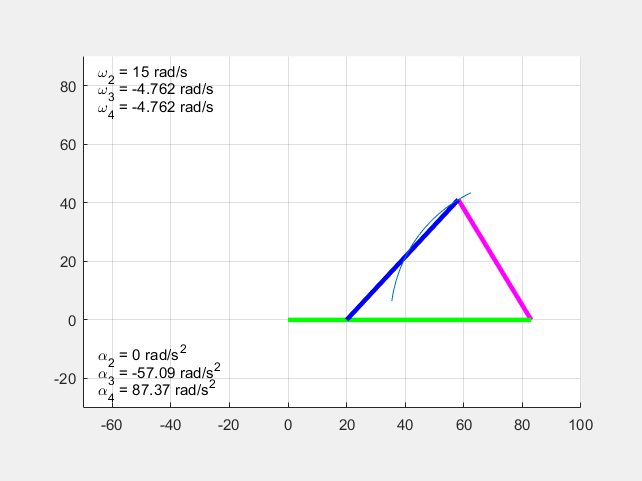

figure('Name','Mecanismo de 4 Barras'); clf;
figure('visible','on')

% Tipo de acoplador
% Acoplador 1 = Barra
% Acoplador 2 = Triangulo
Acoplador = 1;

% Dirección de rotación de eslabón de entrada
% Counterclockwise = 1
% Clockwise = 2
Direccion = 2;

% Graficar trayectoria descrita por acoplador
% Si = 1
% No = 0
Trayectoria = 1;

% Guardar frames de animación en directorio seleccionado
% Si = 1
% No = 0
SaveFrames = 0;

hold on; axis equal; grid on;
XLimInf = -70;
XLimSup = 100;
YLimInf = -30;
YLimSup = 90;
axis([XLimInf XLimSup YLimInf YLimSup]);

TrayectoriaX = [];
TrayectoriaY = [];
j = 1;

% Posiciones para cada uno de los ángulos
PosXVelocidad = ((XLimSup - XLimInf)/100 * 3) + XLimInf;
PosYVelocidad = YLimSup - ((YLimSup - YLimInf)/100 * 5);
DeltaY = (YLimSup - YLimInf)/100 * 5;

% Ángulos a graficar según condición de Grashof
if Grashof == "No Grashof"
    Theta2_Index = [Theta2_Limites(Modo,2):361 1:Theta2_Limites(Modo,1)];
else
    Theta2_Index = 1:361;
end

% Ángulos a graficar según dirección
if Direccion == 2
    Theta2_Index = fliplr(Theta2_Index);
end

% Animación
for i = Theta2_Index
    cla; 
    
    % Velocidades Angulares
    text(PosXVelocidad,PosYVelocidad, strcat("\omega_2 = ", num2str(Omega2(i),4), " rad/s"));
    text(PosXVelocidad,PosYVelocidad - DeltaY, strcat("\omega_3 = ", num2str(Omega3(i),4), " rad/s"));
    text(PosXVelocidad,PosYVelocidad - 2*DeltaY, strcat("\omega_4 = ", num2str(Omega4(i),4), " rad/s"));
    text(PosXVelocidad,YLimInf + 3*DeltaY, strcat("\alpha_2 = ", num2str(Alpha2), " rad/s^2"));
    text(PosXVelocidad,YLimInf + 2*DeltaY, strcat("\alpha_3 = ", num2str(Alpha3(i),4), " rad/s^2"));
    text(PosXVelocidad,YLimInf + 1*DeltaY, strcat("\alpha_4 = ", num2str(Alpha4(i),4), " rad/s^2"));
    
    % Eslabón A (Entrada)
    animatedline([0 a*cosd(Theta2(i))], [0 a*sind(Theta2(i))], 'Color','r','LineWidth',3);
    
    % Eslabón C (Salida)
    animatedline([d*cosd(GlobalOffset) d*cosd(GlobalOffset)+c*cosd(Theta4(Modo,i))], [d*sind(GlobalOffset) d*sind(GlobalOffset)+c*sind(Theta4(Modo,i))], 'Color', 'm', 'LineWidth',3);
    
    % Eslabón D (Bancada)
    animatedline([0 d*cosd(GlobalOffset)], [0 d*sind(GlobalOffset)], 'Color','g','LineWidth',3);
    
    % Eslabón B (Acoplador)
    if Acoplador == 1
        animatedline([a*cosd(Theta2(i)) a*cosd(Theta2(i))+b*cosd(Theta3(Modo,i))], [a*sind(Theta2(i)) a*sind(Theta2(i))+b*sind(Theta3(Modo,i))], 'Color', 'b', 'LineWidth',3);
        PuntoB = [a*cosd(Theta2(i))+b*cosd(Theta3(Modo,i)) a*sind(Theta2(i))+b*sind(Theta3(Modo,i))];
    
    elseif Acoplador == 2
        % Coordenadas Vertices Triangulo
        PuntoA = [a*cosd(Theta2(i)) a*sind(Theta2(i))];
        PuntoB = [a*cosd(Theta2(i))+b*cosd(Theta3(Modo,i)) a*sind(Theta2(i))+b*sind(Theta3(Modo,i))];
        PuntaTriangulo = [PuntoB(1)-l*cosd(Theta3(Modo,i))+r*cosd(Theta3(Modo,i) + 90) PuntoB(2)-l*sind(Theta3(Modo,i))+r*sind(Theta3(Modo,i) + 90)];
        patch([PuntoA(1) PuntoB(1) PuntaTriangulo(1)],[PuntoA(2) PuntoB(2) PuntaTriangulo(2)], 'yellow');   
    end
    
     % Graficación de trayectoria generada
     if Trayectoria == 1
        TrayectoriaX = [TrayectoriaX PuntoB(1)];
        TrayectoriaY = [TrayectoriaY PuntoB(2)];
        plot(TrayectoriaX, TrayectoriaY);
     end 
    
    % Guardado de Frames Numeradas
    if SaveFrames == 1
        if mod(i,2) == 0
            saveas(gcf, strcat('Pos',num2str(j),'.png'));
            j = j + 1;
        end
    end
    
    drawnow
end

### Mecanismo Manivela Corredera

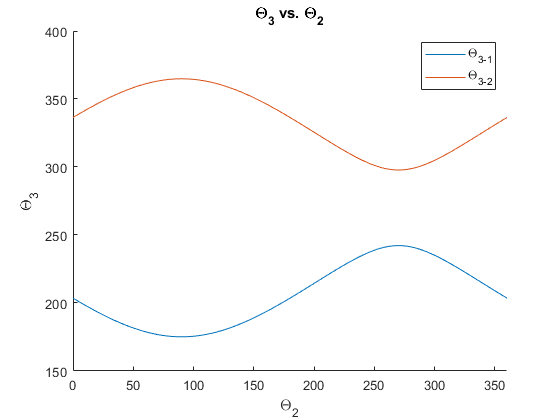

% Vector con todos los ángulos de 0 a 360
clear;
Theta2 = linspace(0,360,361);

% Transformación con respecto a las "Coordenadas Globales"
% Ángulos positivos = Ángulo por encima del eje X
% Ángulos negativos = Ángulo por debajo del eje Y
GlobalOffset = 0;

% Largo de cada eslabón
a = 63;
b = 130;
c = 52;

% Theta 3
Theta3(2,:) = asind((a*sind(Theta2) - c) / b) + GlobalOffset;
Theta3(1,:) = asind(-(a*sind(Theta2) - c) / b) + 180 + GlobalOffset;

for i = 1:2
    if isempty(Theta3(Theta3(i,:) < 0)) == 0
        Theta3(i,:) = Theta3(i,:) + 360;
    end
end

Theta2 = Theta2 + GlobalOffset;

figure(6); clf; hold on
plot(Theta2, Theta3(1,:));
plot(Theta2, Theta3(2,:));
legend("\Theta_{3-1}", "\Theta_{3-2}")
title("\Theta_{3} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{3}");
xlim([GlobalOffset 360+GlobalOffset])

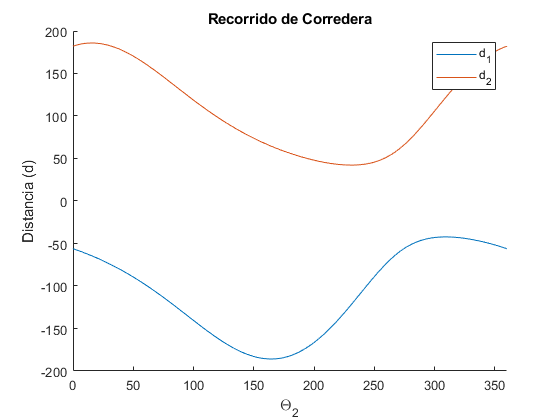


% Distancia Horizontal Corredera (d)
d(2,:) = a*cosd(Theta2-GlobalOffset) - b*cosd(Theta3(1,:)-GlobalOffset);
d(1,:) = a*cosd(Theta2-GlobalOffset) - b*cosd(Theta3(2,:)-GlobalOffset);

figure(7); clf; hold on
plot(Theta2, d(1,:));
plot(Theta2, d(2,:));
legend("d_1", "d_2")
title("Recorrido de Corredera");
xlabel("\Theta_2");
ylabel("Distancia (d)");
xlim([GlobalOffset 360+GlobalOffset])


% Cálculo de Carrera
Carrera(1) = max(d(1,:)) - min(d(1,:));
Carrera(2) = max(d(2,:)) - min(d(2,:));

% Compensamiento de Theta 3 para obtener ángulos 
% utilizables en la animación posterior
Theta3 = Theta3 - 180;

#### Animación del Mecanismo

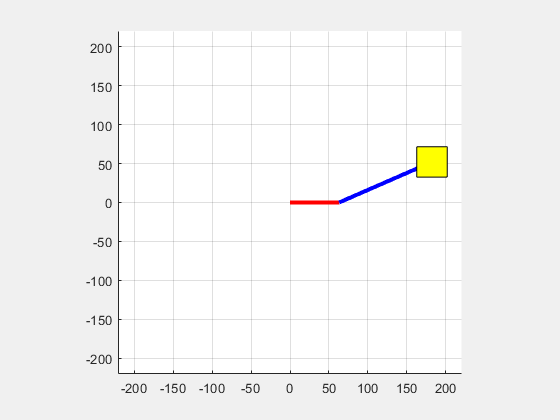

figure(8); clf;
figure('visible','on')

% Modo a animar
% Modo 1 = Normal
% Modo 2 = Cruzado
Modo = 1;

hold on; axis equal; grid on;

% Establecimiento de Límites
Margen = 1.5;
axis([-220 220 -220 220]);

PosFinalA(1,:) = a*cosd(Theta2);
PosFinalA(2,:) = a*sind(Theta2);

% Animación
for i = 1:361
    cla; 
    
    % Eslabón A
    animatedline([0 PosFinalA(1,i)], [0 PosFinalA(2,i)], 'Color','r','LineWidth',3);
    
    % Eslabón B
    animatedline([PosFinalA(1,i) PosFinalA(1,i)+b*cosd(Theta3(Modo,i))], [PosFinalA(2,i) PosFinalA(2,i)+b*sind(Theta3(Modo,i))], 'Color', 'b', 'LineWidth',3);
    
    % Pistón
    CentroPistonXInf = a*cosd(Theta2(i)) + b*cosd(Theta3(Modo,i)) - (b*0.3/2)*cosd(GlobalOffset);
    CentroPistonXSup = a*cosd(Theta2(i)) + b*cosd(Theta3(Modo,i)) + (b*0.3/2)*cosd(GlobalOffset);
    CentroPistonYInf = a*sind(Theta2(i)) + b*sind(Theta3(Modo,i)) - (b*0.3/2)*sind(GlobalOffset);
    CentroPistonYSup = a*sind(Theta2(i)) + b*sind(Theta3(Modo,i)) + (b*0.3/2)*sind(GlobalOffset);
    AjusteX = (b*0.3/2)*cosd(90 - GlobalOffset);
    AjusteY = (b*0.3/2)*sind(90 - GlobalOffset);
    
    patch([CentroPistonXInf+AjusteX CentroPistonXInf-AjusteX CentroPistonXSup-AjusteX CentroPistonXSup+AjusteX],[CentroPistonYInf-AjusteY CentroPistonYInf+AjusteY CentroPistonYSup+AjusteY CentroPistonYSup-AjusteY], 'yellow');
    
    drawnow
    
end

### Mecanismo de 5 Barras

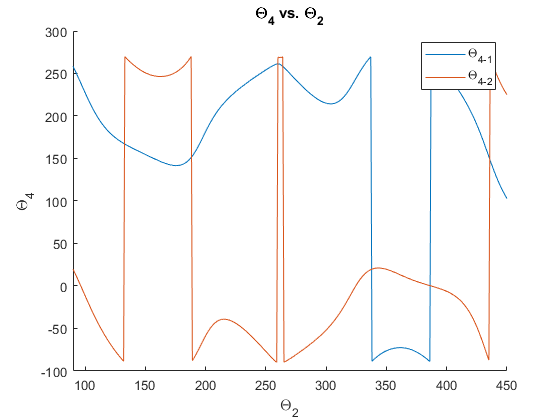


% Offset Global
clear;
GlobalOffset = 90;

% Longitudes de eslabón
a = 5;
b = 7;
c = 8;
d = 4; 
f = 6;
Lambda = -2.5;
Phi = 60;

% Vector con todos los ángulos de 0 a 360
Theta2 = linspace(0,360,361);
Theta5 = Theta2*Lambda + Phi;

% Theta 4
A = 2*c*(d*cosd(Lambda*Theta2 + Phi) - a*cosd(Theta2) + f);
B = 2*c*(d*sind(Lambda*Theta2 + Phi) - a*sind(Theta2));
C = a^2 - b^2 + c^2 + d^2 + f^2 - 2*a*f*cosd(Theta2) ...
    -2*d*(a*cosd(Theta2) - f).*cosd(Lambda*Theta2 + Phi) ...
    -2*a*d*sind(Theta2).*sind(Lambda*Theta2 + Phi);

D = C - A;
E = 2*B;
F = A + C;

Theta4(1,:) = 2*atand((-E - sqrt(E.^2 - 4*D.*F))./(2*D)) + GlobalOffset;
Theta4(2,:) = 2*atand((-E + sqrt(E.^2 - 4*D.*F))./(2*D)) + GlobalOffset;

Theta2 = Theta2 + GlobalOffset;

figure(9); clf; hold on
plot(Theta2, real(Theta4(1,:)));
plot(Theta2, real(Theta4(2,:)));
legend("\Theta_{4-1}", "\Theta_{4-2}")
title("\Theta_{4} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{4}");
xlim([GlobalOffset 360+GlobalOffset])

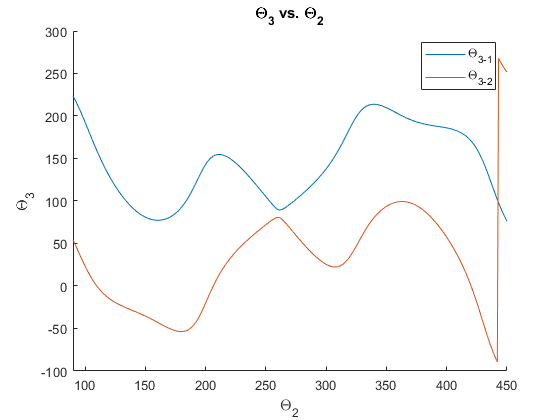


Theta2 = Theta2 - GlobalOffset;

% Theta 3
G = 2*b*(a*cosd(Theta2) - d*cosd(Lambda*Theta2 + Phi) - f);
H = 2*b*(a*sind(Theta2) - d*sind(Lambda*Theta2 + Phi));
K = a^2 + b^2 - c^2 + d^2 + f^2 - 2*a*f*cosd(Theta2) ...
    -2*d*(a*cosd(Theta2) - f).*cosd(Lambda*Theta2 + Phi) ...
    -2*a*d*sind(Theta2).*sind(Lambda*Theta2 + Phi);

L = K - G;
M = 2*H;
N = G + K;

Theta3(1,:) = 2*atand((-M+sqrt(M.^2-4*L.*N))./(2*L)) + GlobalOffset;
Theta3(2,:) = 2*atand((-M-sqrt(M.^2-4*L.*N))./(2*L)) + GlobalOffset;

Theta2 = Theta2 + GlobalOffset;
Theta5 = Theta5 + GlobalOffset;

figure(10); clf; hold on
plot(Theta2, real(Theta3(1,:)));
plot(Theta2, real(Theta3(2,:)));
legend("\Theta_{3-1}", "\Theta_{3-2}")
title("\Theta_{3} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{3}");
xlim([GlobalOffset 360+GlobalOffset])

#### Animación del Mecanismo

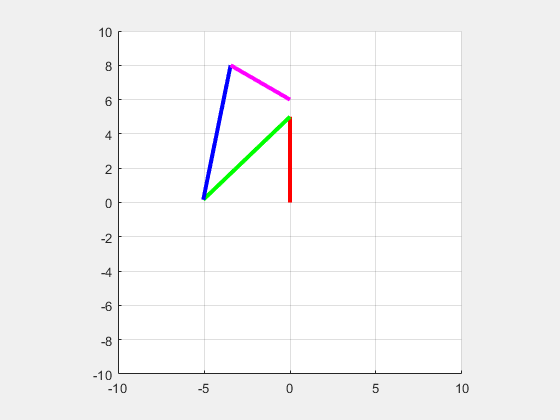

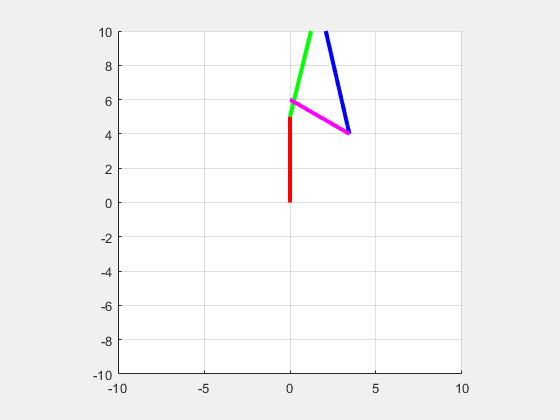

figure(11); clf;
figure('visible','on')

% Modo a animar
% Modo 1 = Normal
% Modo 2 = Cruzado
Modo = 1;

hold on; axis equal; grid on;

% Establecimiento de Límites
axis([-10 10 -10 10]);

% Animación
for i = 1:361
    cla; 
    
    % Eslabón A
    animatedline([0 a*cosd(Theta2(i));], [0 a*sind(Theta2(i));], 'Color','r','LineWidth',3);
    
    % Eslabón B
    animatedline([a*cosd(Theta2(i)) a*cosd(Theta2(i))+b*cosd(real(Theta3(Modo,i)))], [a*sind(Theta2(i)) a*sind(Theta2(i))+b*sind(real(Theta3(Modo,i)))], 'Color', 'g', 'LineWidth',3);
    
    % Eslabón C
    animatedline([f*cosd(GlobalOffset)+d*cosd(Theta5(i)) f*cosd(GlobalOffset)+d*cosd(Theta5(i))+c*cosd(real(Theta4(Modo,i)))], [f*sind(GlobalOffset)+d*sind(Theta5(i)) f*sind(GlobalOffset)+d*sind(Theta5(i))+c*sind(real(Theta4(Modo,i)))], 'Color', 'b', 'LineWidth',3);
    
    % Eslabón D
    animatedline([f*cosd(GlobalOffset) f*cosd(GlobalOffset)+d*cosd(Theta5(i))], [f*sind(GlobalOffset) f*sind(GlobalOffset)+d*sind(Theta5(i))], 'Color', 'm', 'LineWidth',3);
    
    drawnow
end

### Manivela Corredera Inversión 3

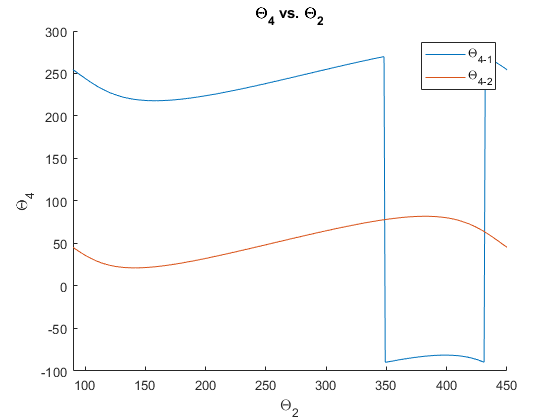


% Offset Global
clear;
GlobalOffset = 90;

% Longitudes de eslabón
a = 4;
c = 2;
d = 8; 
Gamma = 30;

% Theta 2
Theta2 = linspace(0,360,361);

% Theta 4

P = a*sind(Theta2)*sind(Gamma) + (a*cosd(Theta2) - d)*cosd(Gamma);
Q = -a*sind(Theta2)*cosd(Gamma) + (a*cosd(Theta2) - d)*sind(Gamma);
R = -c*sind(Gamma);

S = R - Q;
T = 2*P;
U = Q + R;

Theta4(1, :) = real(2*atand((-T + sqrt(T.^2 - 4*S.*U))./(2*S)));
Theta4(2, :) = real(2*atand((-T - sqrt(T.^2 - 4*S.*U))./(2*S)));

% Theta 3

Theta3(1, :) = Theta4(1, :) + Gamma;
Theta3(2, :) = Theta4(2, :) + Gamma;

% Distancia B

b(1,:) = (a*sind(Theta2) - c*sind(Theta4(1,:)))./sind(Theta3(1,:));
b(2,:) = (a*sind(Theta2) - c*sind(Theta4(2,:)))./sind(Theta3(2,:));

% Ajuste de Global Offset

Theta4 = Theta4 + GlobalOffset;
Theta3 = Theta3 + GlobalOffset;
Theta2 = Theta2 + GlobalOffset;

figure(12); clf; hold on
plot(Theta2, Theta4(1,:));
plot(Theta2, Theta4(2,:));
legend("\Theta_{4-1}", "\Theta_{4-2}")
title("\Theta_{4} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{4}");
xlim([GlobalOffset 360+GlobalOffset])

#### Animación del Mecanismo

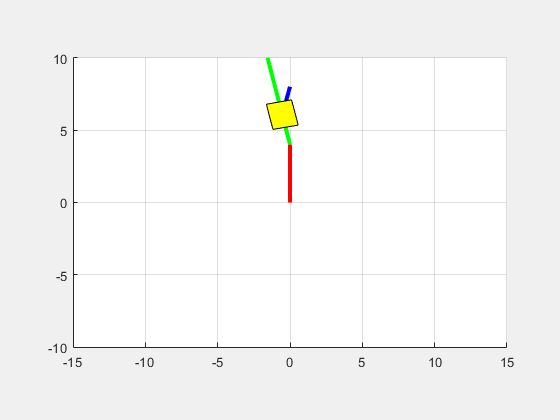

figure(13); clf;
figure('visible','on')

% Modo a animar
% Modo 1 = Normal
% Modo 2 = Cruzado
Modo = 1;

hold on; axis equal; grid on;

% Establecimiento de Límites
axis([-15 15 -10 10]);

% Animación
for i = 1:361
    cla; 
    
    % Eslabón A
    animatedline([0 a*cosd(Theta2(i));], [0 a*sind(Theta2(i));], 'Color','r','LineWidth',3);
    
    % Eslabón B
    animatedline([a*cosd(Theta2(i)) a*cosd(Theta2(i))+(a+c+d)*sign(b(Modo,i))*cosd(Theta3(Modo,i) - 180)], [a*sind(Theta2(i)) a*sind(Theta2(i))+(a+c+d)*sign(b(Modo,i))*sind(Theta3(Modo,i) - 180)], 'Color', 'g', 'LineWidth',3);
    
    % Eslabón C
    animatedline([d*cosd(GlobalOffset) d*cosd(GlobalOffset)+c*cosd(Theta4(Modo,i))], [d*sind(GlobalOffset) d*sind(GlobalOffset)+c*sind(Theta4(Modo,i))], 'Color', 'b', 'LineWidth',3);
    
    % Corredera
    CentroPistonXInf = a*cosd(Theta2(i)) + b(Modo,i)*cosd(Theta3(Modo,i) - 180) - ((a+c)*0.3/2)*cosd(Theta3(Modo,i) - 180);
    CentroPistonXSup = a*cosd(Theta2(i)) + b(Modo,i)*cosd(Theta3(Modo,i) - 180) + ((a+c)*0.3/2)*cosd(Theta3(Modo,i) - 180);
    CentroPistonYInf = a*sind(Theta2(i)) + b(Modo,i)*sind(Theta3(Modo,i) - 180) - ((a+c)*0.3/2)*sind(Theta3(Modo,i) - 180);
    CentroPistonYSup = a*sind(Theta2(i)) + b(Modo,i)*sind(Theta3(Modo,i) - 180) + ((a+c)*0.3/2)*sind(Theta3(Modo,i) - 180);
    AjusteX = ((a+c)*0.3/2)*cosd(90 - Theta3(Modo,i) - 180);
    AjusteY = ((a+c)*0.2/2)*sind(90 - Theta3(Modo,i) - 180);
    
    patch([CentroPistonXInf+AjusteX CentroPistonXInf-AjusteX CentroPistonXSup-AjusteX CentroPistonXSup+AjusteX],[CentroPistonYInf-AjusteY CentroPistonYInf+AjusteY CentroPistonYSup+AjusteY CentroPistonYSup-AjusteY], 'yellow');
    
    drawnow
end

### Mecanismo de 6 Barras de Watt

% Vector con todos los ángulos de 0 a 360
clear;
Theta2 = linspace(0,360,361);

% Transformación con respecto a las "Coordenadas Globales"
% Ángulos positivos = Ángulo por encima del eje X
% Ángulos negativos = Ángulo por debajo del eje Y
GlobalOffset = 0;

% Largo de cada eslabón
d = 150;
a = 30;
b = 150;
c = 30;

% Constantes K
K1 = d/a;
K2 = d/c;
K3 = (a^2 - b^2 + c^2 + d^2)/(2*a*c);
K4 = d/b;
K5 = (c^2 - d^2 - a^2 - b^2)/(2*a*b);

% Constantes A-F
A = cosd(Theta2) - K1 - (K2 .* cosd(Theta2)) + K3;
B = -2 * sind(Theta2);
C = K1 - ((K2+1) .* cosd(Theta2)) + K3;
D = cosd(Theta2) - K1 + (K4 .* cosd(Theta2)) + K5;
E = -2 .* sind(Theta2);
F = K1 + ((K4-1) .* cosd(Theta2)) + K5;

% Theta 4
Theta4(1,:) = 2*atand((-B-sqrt(B.^2 - 4*A.*C))./(2.*A)) + GlobalOffset;
Theta4(2,:) = 2*atand((-B+sqrt(B.^2 - 4*A.*C))./(2.*A)) + GlobalOffset;

Theta2 = Theta2 + GlobalOffset;

for i = 1:2
    if isempty(Theta4(Theta4(i,:) < 0)) == 0
        Theta4(i,:) = Theta4(i,:) + 360;
    end
end

figure(1); clf; hold on
plot(Theta2, Theta4(1,:));
plot(Theta2, Theta4(2,:));
legend("\Theta_{4-1}", "\Theta_{4-2}")
title("\Theta_{4} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{4}");
xlim([GlobalOffset 360+GlobalOffset])
Theta2 = Theta2 - GlobalOffset;

% Theta 3
Theta3(1,:) = 2*atand((-E-sqrt(E.^2 - 4.*D.*F))./(2.*D)) + GlobalOffset;
Theta3(2,:) = 2*atand((-E+sqrt(E.^2 - 4.*D.*F))./(2.*D)) + GlobalOffset;

Theta2 = Theta2 + GlobalOffset;

for i = 1:2
    if isempty(Theta3(Theta3(i,:) < 0)) == 0
        Theta3(i,:) = Theta3(i,:) + 360;
    end
end

figure(2); clf; hold on
plot(Theta2, Theta3(1,:));
plot(Theta2, Theta3(2,:));
legend("\Theta_{3-1}", "\Theta_{3-2}")
title("\Theta_{3} vs. \Theta_2");
xlabel("\Theta_2");
ylabel("\Theta_{3}");
xlim([GlobalOffset 360+GlobalOffset])

% Ángulo de Transmisión
Mu = abs(Theta3 - Theta4);
Mu(Mu > 90) = 180 - Mu(Mu > 90);

figure(3); clf;
plot(Theta2, Mu);
title("\mu vs. \Theta_2");
legend("\mu_1", "\mu_2")
xlabel("\Theta_2");
ylabel("\mu");
xlim([GlobalOffset 360+GlobalOffset])